# Setting up and simulate an ILC system

clear; close all;

## setting up the dynamics

Setting up the dynamics of the stabilized robot.

% load previously designed model
load('chabo_ol_dynamics_disc.mat');
% design LQR matrices
qPitch              = 1;
qPitchVelocity      = 0;
qPosition           = 10;
qSpeed              = 0;
qFlywheelVelocity   = 0.0001;
rTires              = 1;
rFlywheel           = 1;
Q                   = diag([qPitch, qPitchVelocity, qPosition, qSpeed, qFlywheelVelocity]);
R                   = diag([rTires, rFlywheel]);
% calculate discrete control matrix via dlqr
Kd                  = dlqr(chabo_ol_disc.A, chabo_ol_disc.B, Q, R);

## load reference

Load a feasible reference which will be learned and performed by the robot. The reference in this script is designed and tuned manually to fullfill the task.

load("designed_ref_forwardDive_45_deg.mat");
N = length(r1);
% design mimo reference
r = reshape([r1'; r2'], 2*N, 1);

## design ILC system

% scalar weights
qW  = 0.5;
sW  = 0.03;
rW  = 0.0;
% matrizes
QW  = qW * eye(2*N);
SW  = sW * eye(2*N);
RW  = rW * eye(2*N);
% derive lifted form of plant dynamics, closed-loop dynamics of the robot
P       = lifted_dynamics_chabo(chabo_ol_disc.A-chabo_ol_disc.B*Kd, chabo_ol_disc.B, chabo_ol_disc.C, N);
% normalize plant dynamics
gamma_P = 1 / norm(P);
% design ILC system
[Q, L] = qilc_design(gamma_P*P, QW, SW, RW);

## simulate results

% number of iterations
J           = 5;      
% initial conditions
x0          = [deg2rad(0); 0; 0; 0; 0; 0];

### simulate ILC with linear model

ilc_data_lin = run_ilc_mimo_linear(r, P, Q, L*gamma_P, J);
%plot latest trial
% plot_ilc_mimo_linear(ilc_data_lin, chabo_ol_disc, Kd, constraints);
% plot ilc progression
% fig_lin_progression = plot_ilc_mimo_linear_progression(ilc_data_lin,chabo_ol_disc, Kd, constraints);

### simulate ILC with nonlinear model

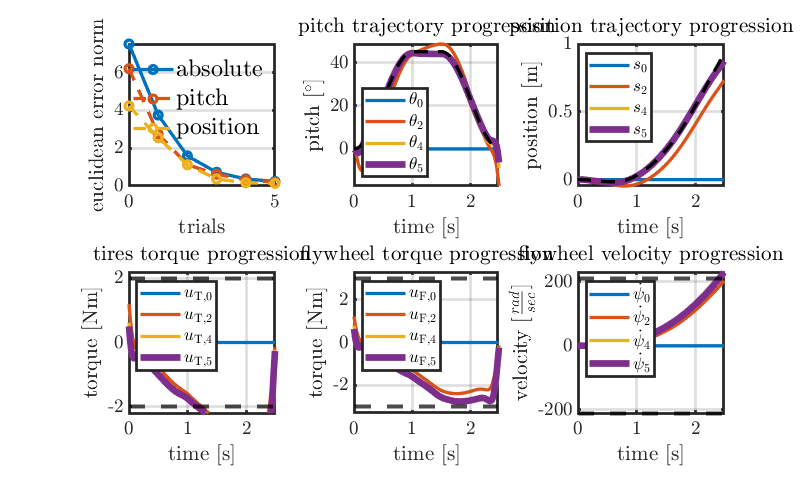

% run ILC with NL model
ilc_data_nonlin = run_ilc_mimo(r,Kd,Q,L*gamma_P,J);
% plot latest trial
% fig_nonlin = plot_ilc_mimo(ilc_data_nonlin, constraints);
% plot ilc progression
fig_nonlin_progression = plot_ilc_mimo_progression(ilc_data_nonlin, constraints);